robot = Qbmove1MD()

robot =   Qbmove1MD with properties:

           dimQ: 1
           dimX: 6
           dimU: 3
        inertia: 0.0300
             Df: 0.0020
           umax: [3×1 double]
           umin: [3×1 double]
       actuator: [1×1 Qbmove]
           Dmax: 0.0085
    alpha_servo: 20



x0 = [0; 0; 0; 0; 0; 0];
tension = 0.5;
qf = pi/3;
xf = [qf; 0; qf+tension; qf-tension; 0; 0 ];
%xf = qf;
testtraj = TrajOptQbmove1MD.reachFastIlqr(robot, x0, xf, 'tf', 1, 'dt', 0.02, 'tension', tension, 'sfactor', 1, 'ConstraintType', 2);

Iteration = 1; Cost = 390.7412; log(Lambda) = 0.2
Iteration = 2; Cost = 390.7412; log(Lambda) = 0.4
Iteration = 3; Cost = 390.7412; log(Lambda) = 0.6
Iteration = 4; Cost = 390.7412; log(Lambda) = 0.8
Iteration = 5; Cost = 390.7412; log(Lambda) = 1.0
Iteration = 6; Cost = 390.7412; log(Lambda) = 1.2
Iteration = 7; Cost = 390.7412; log(Lambda) = 1.4
Iteration = 8; Cost = 374.1366; log(Lambda) = 1.2
Optimal control law and cost-to-go computation diverged. 
Elapsed time is 0.412102 seconds.
ILQR done


testtraj.SettlingTime

Reference to non-existent field 'SettlingTime'.

%stepinfo(testtraj.x(1,:), testtraj.t, 0.7, 'SettlingTimeShreshold', 0.02 )

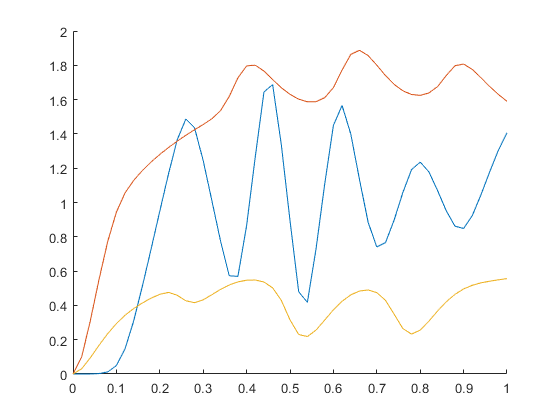

figure
hold on
plot(testtraj.t, testtraj.x(1,:))
plot(testtraj.t, testtraj.x(3,:))
plot(testtraj.t, testtraj.x(4,:))
hold off

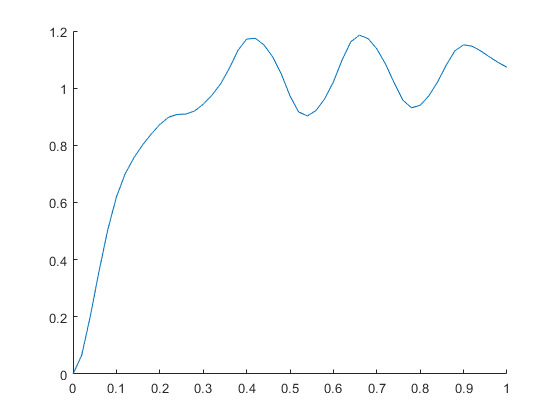


figure
hold on
plot(testtraj.t, (testtraj.x(3,:)+testtraj.x(4,:))/2)
hold off

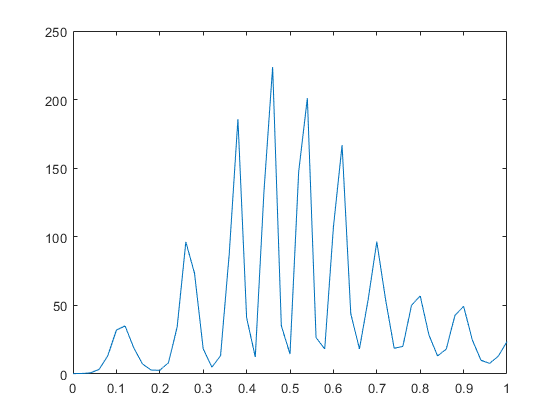


figure
plot(testtraj.t, robot.stiffness(testtraj.x))

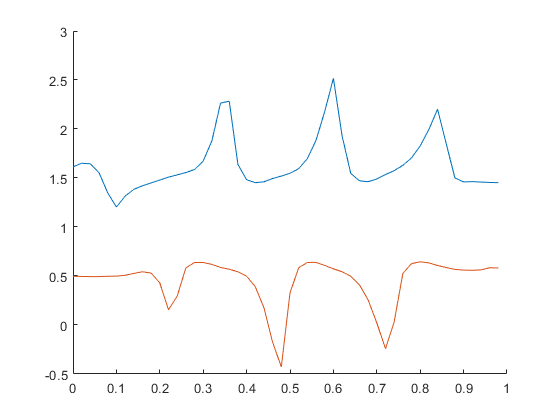


figure
hold on
xlim('auto')
ylim('auto')
plot(testtraj.t(1:end-1), testtraj.u(1,:))

xlim('auto')
ylim('auto')
plot(testtraj.t(1:end-1), testtraj.u(2,:))
hold off